[features, labels] = loadFeatures('archive', 'Training');
features = normalize(features, 'range');

numClasses = numel(unique(labels));
YAll = full(ind2vec(labels'))';


=== Fold 1 of 10 ===


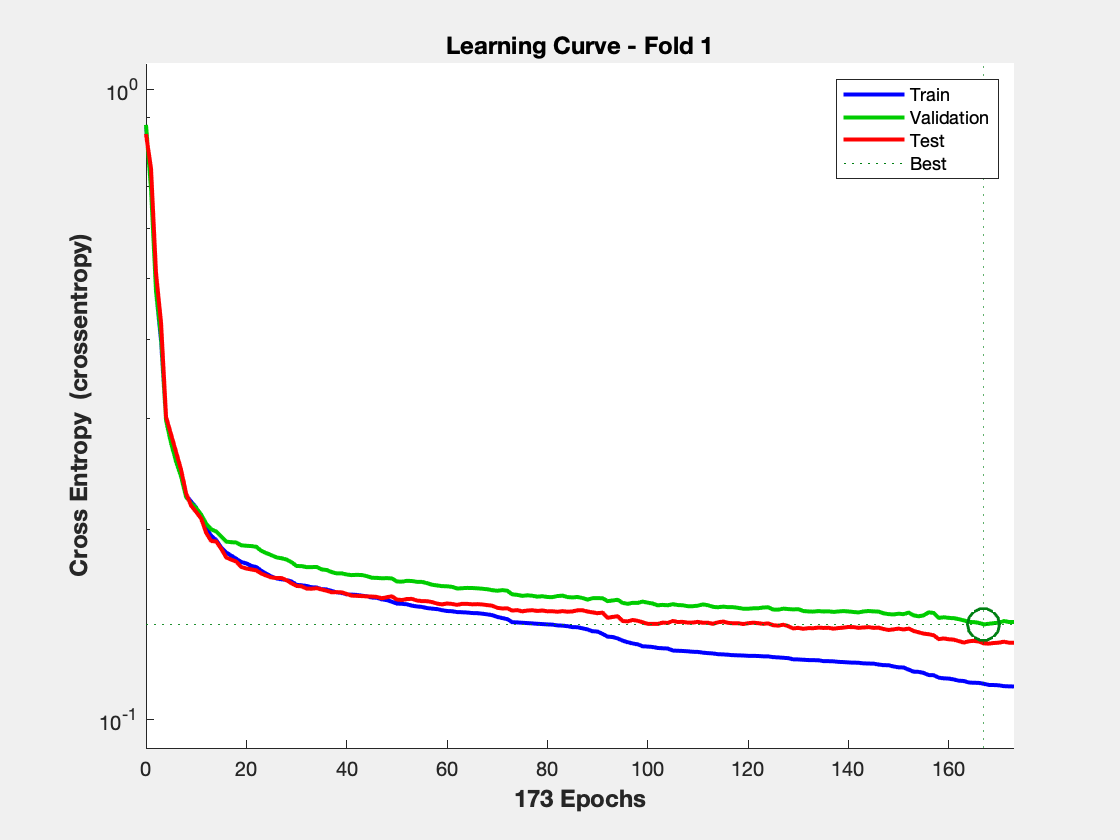

Fold 1 Accuracy: 78.06%


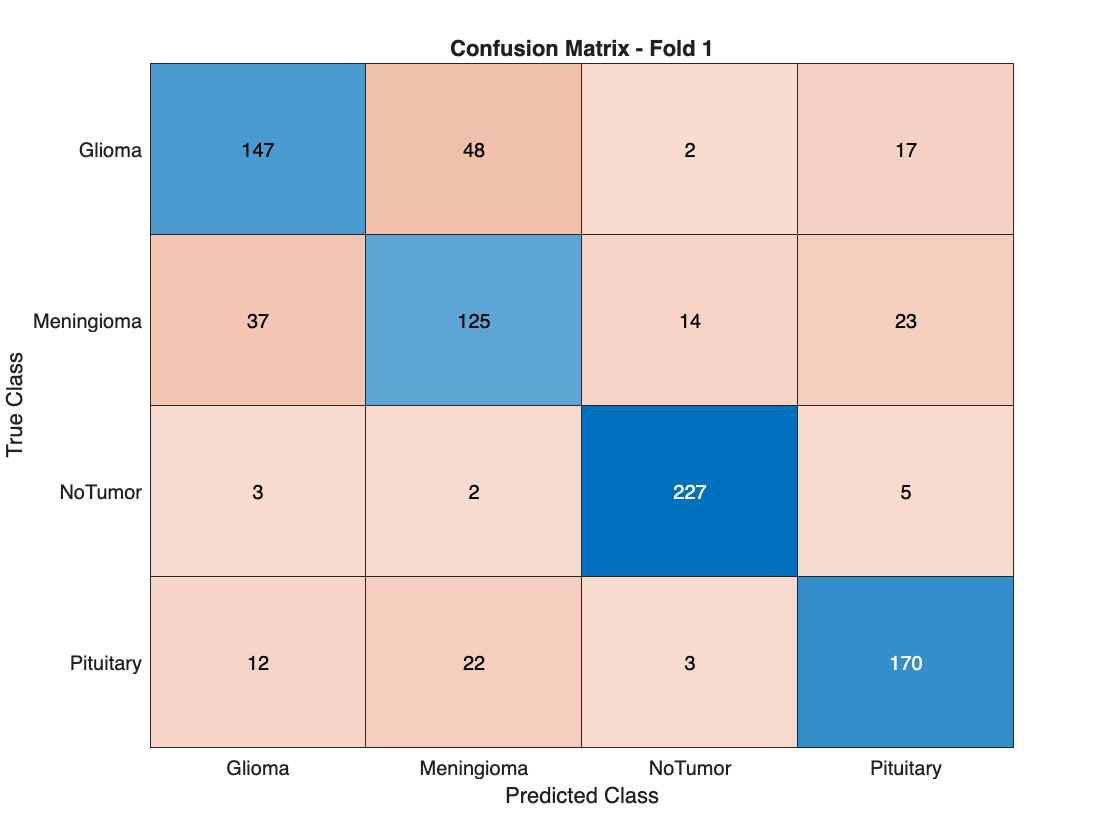


=== Fold 2 of 10 ===


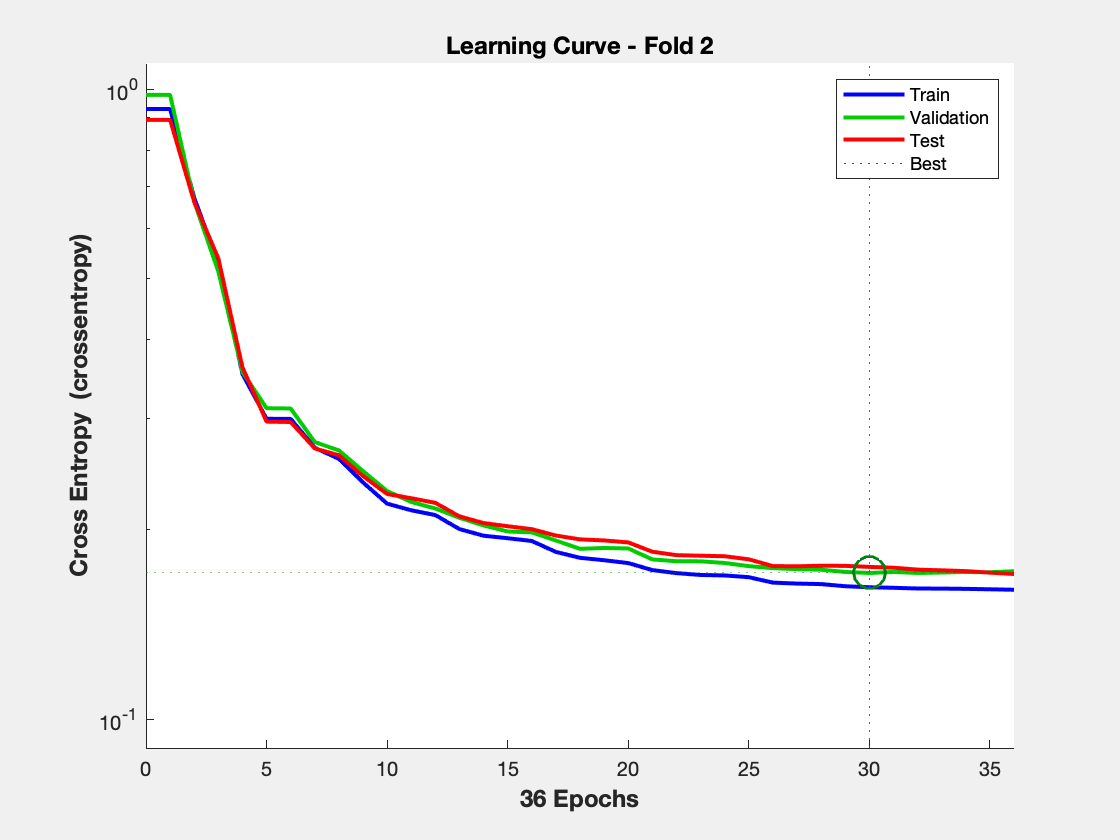

Fold 2 Accuracy: 73.51%


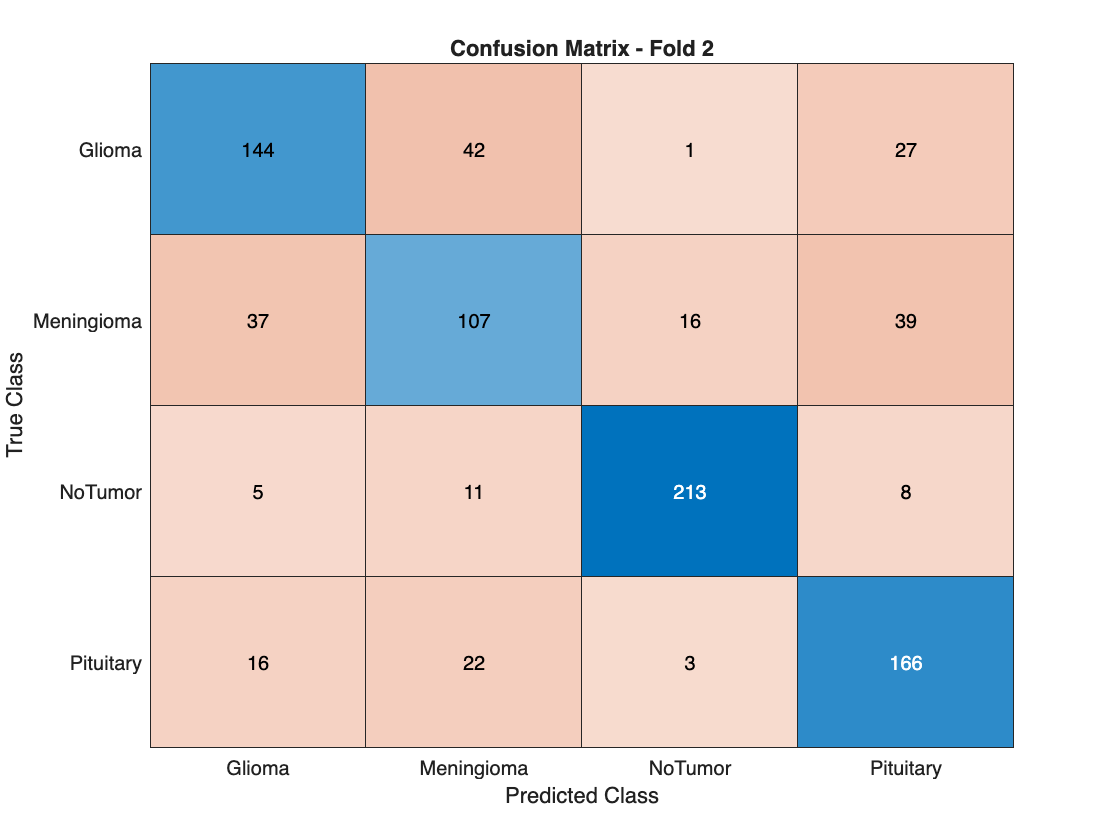


=== Fold 3 of 10 ===


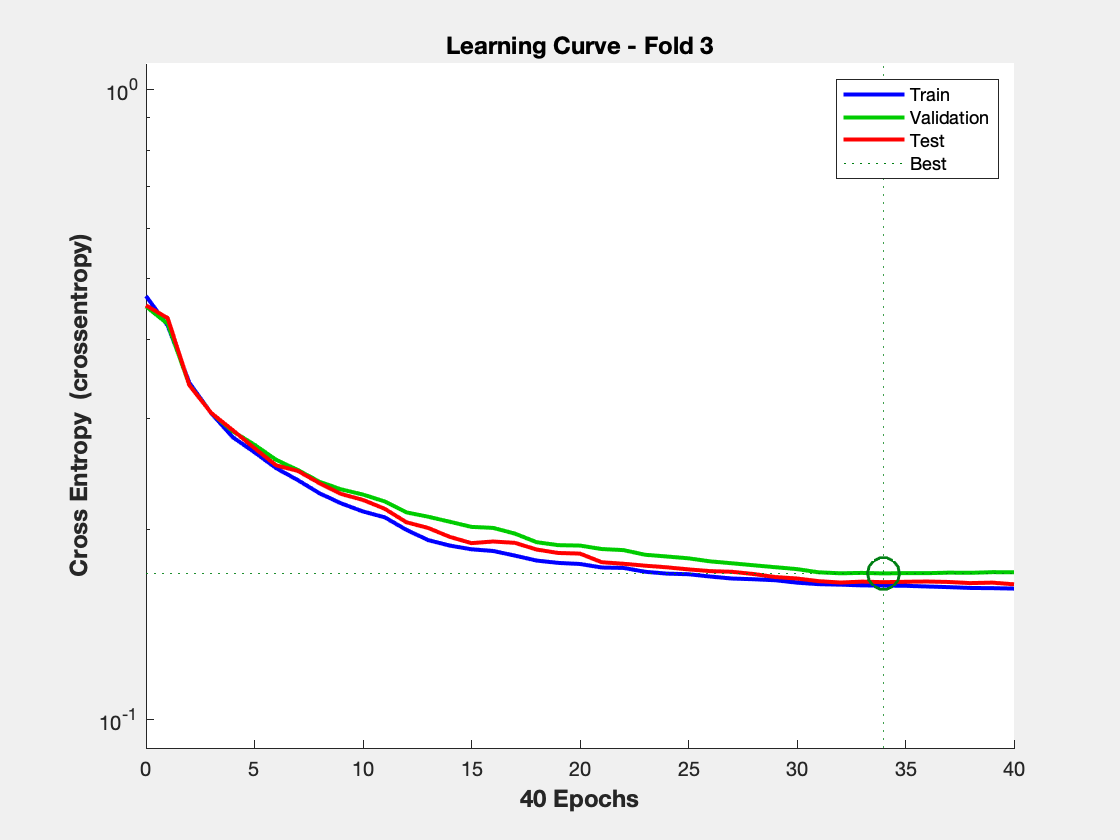

Fold 3 Accuracy: 74.10%


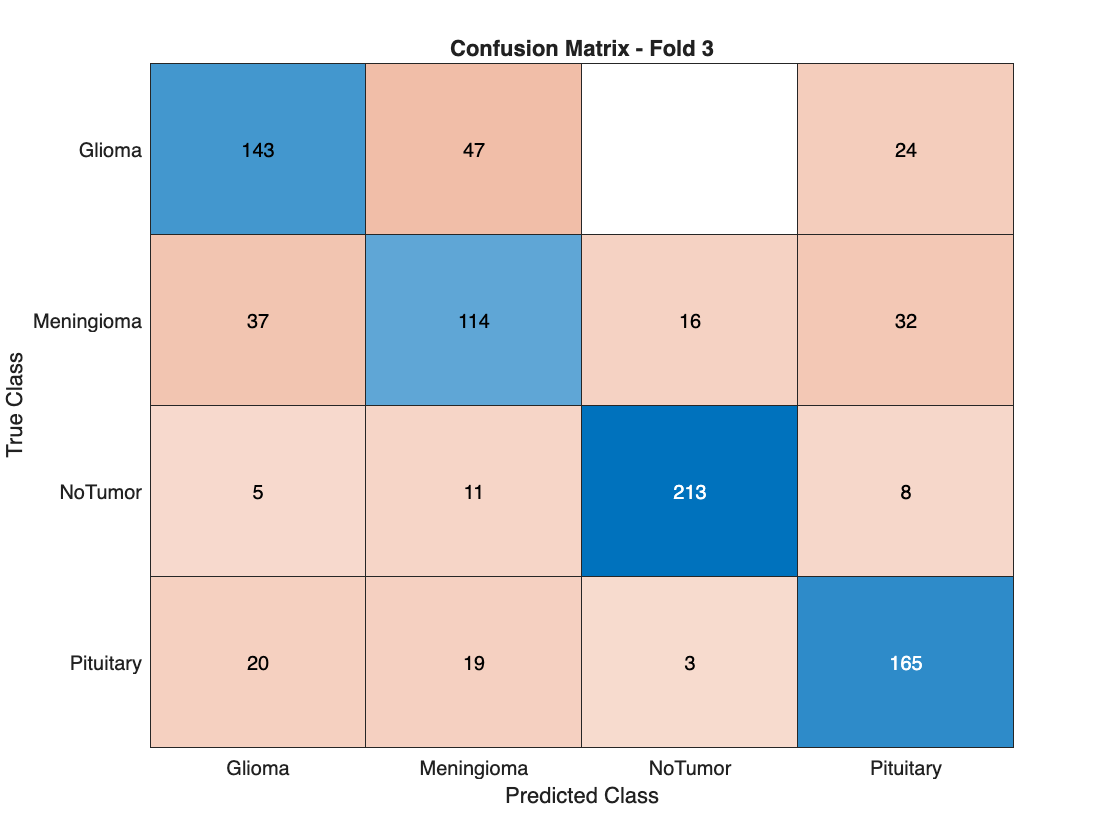


=== Fold 4 of 10 ===


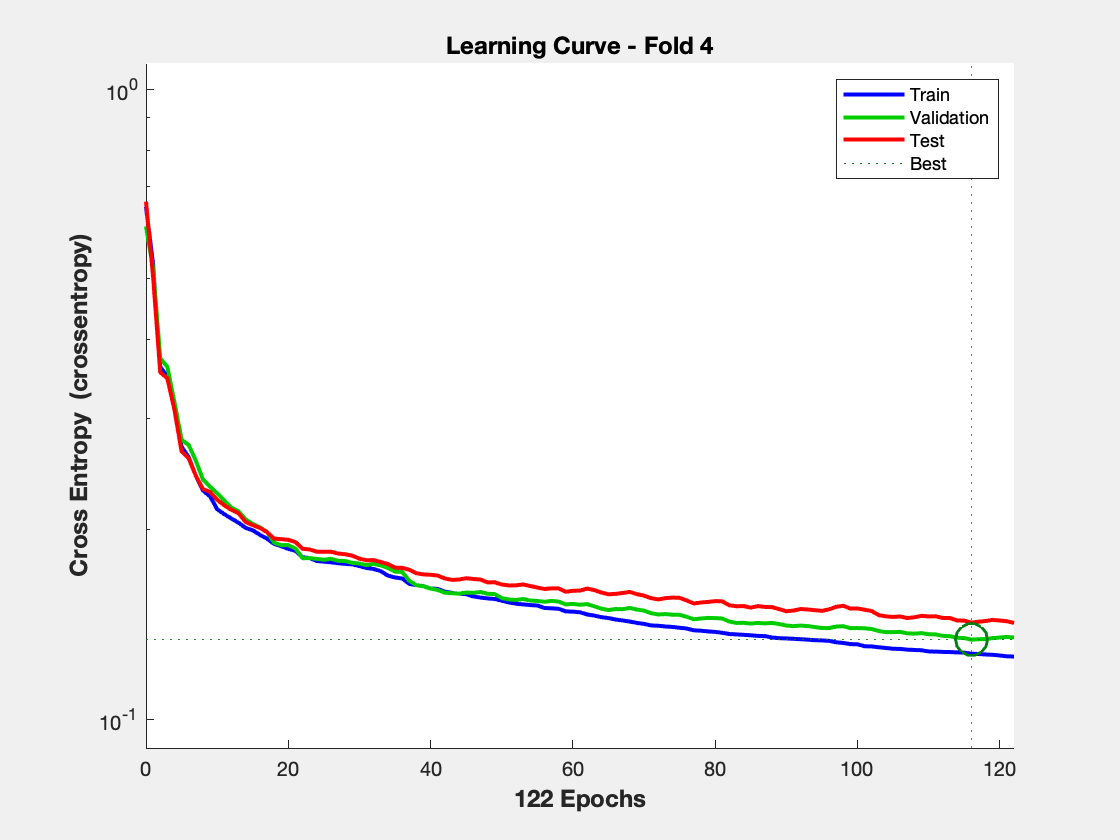

Fold 4 Accuracy: 78.41%


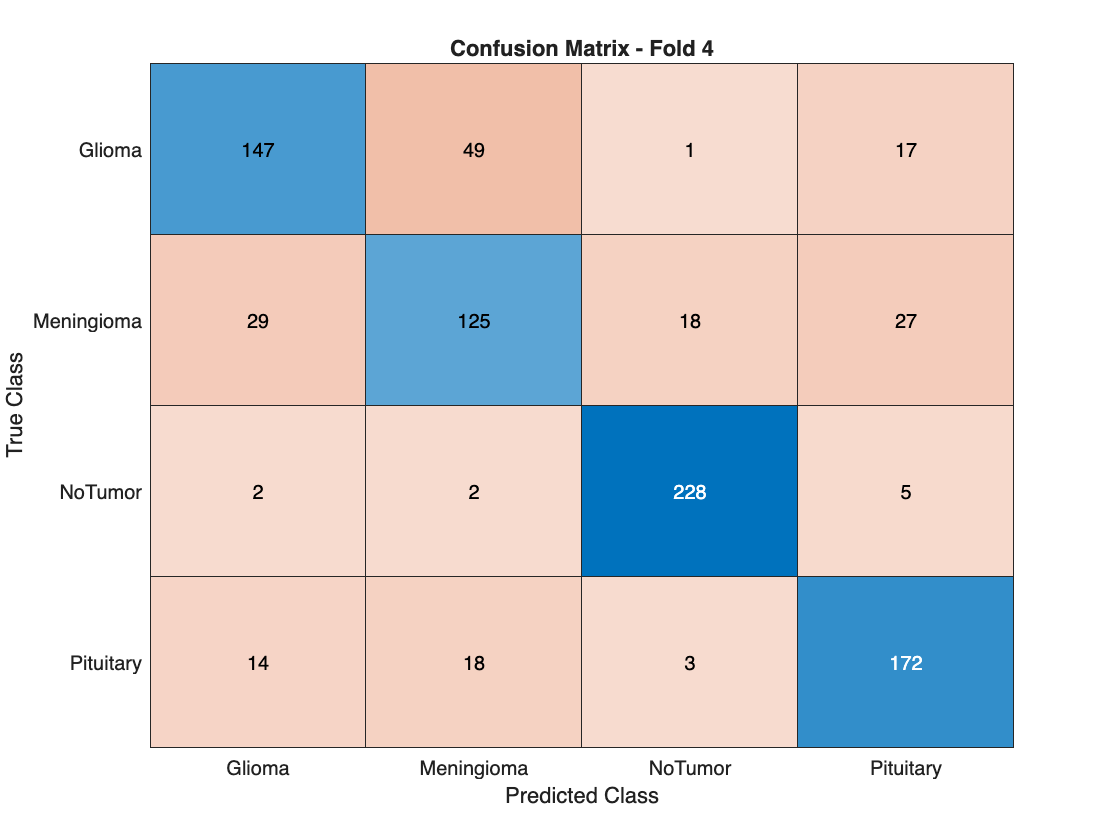


=== Fold 5 of 10 ===


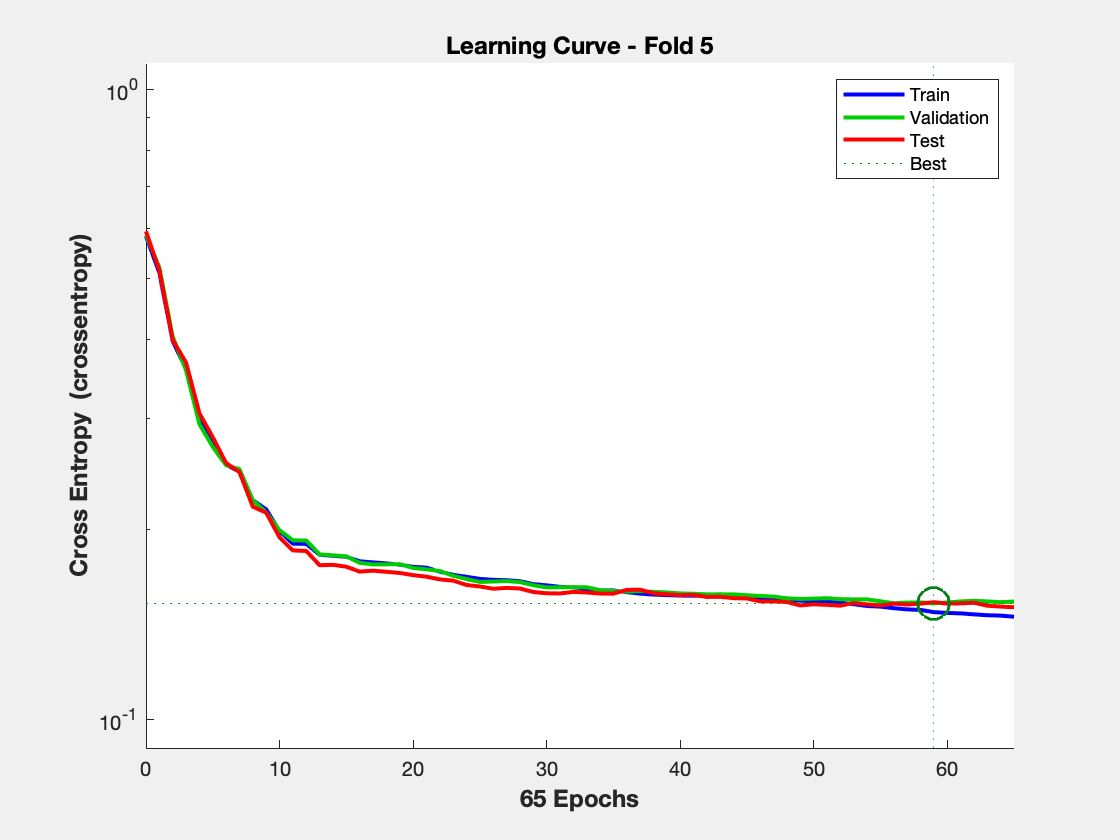

Fold 5 Accuracy: 76.20%


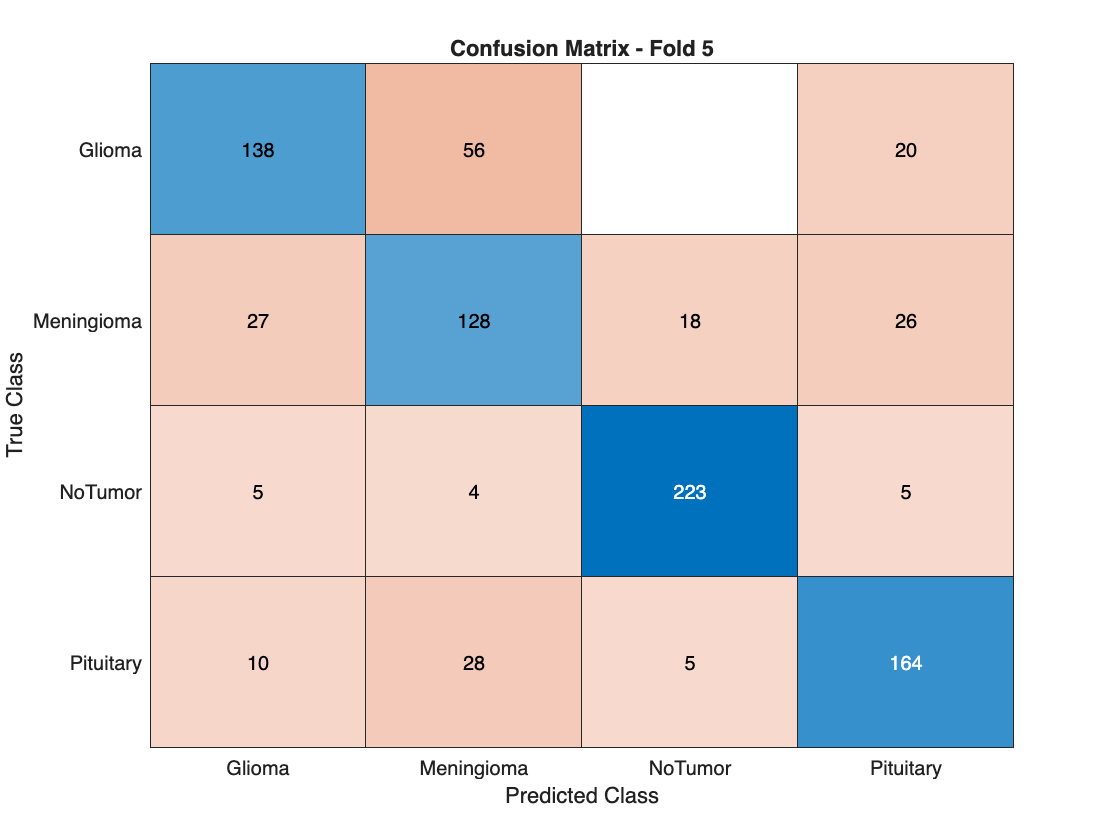


=== Fold 6 of 10 ===


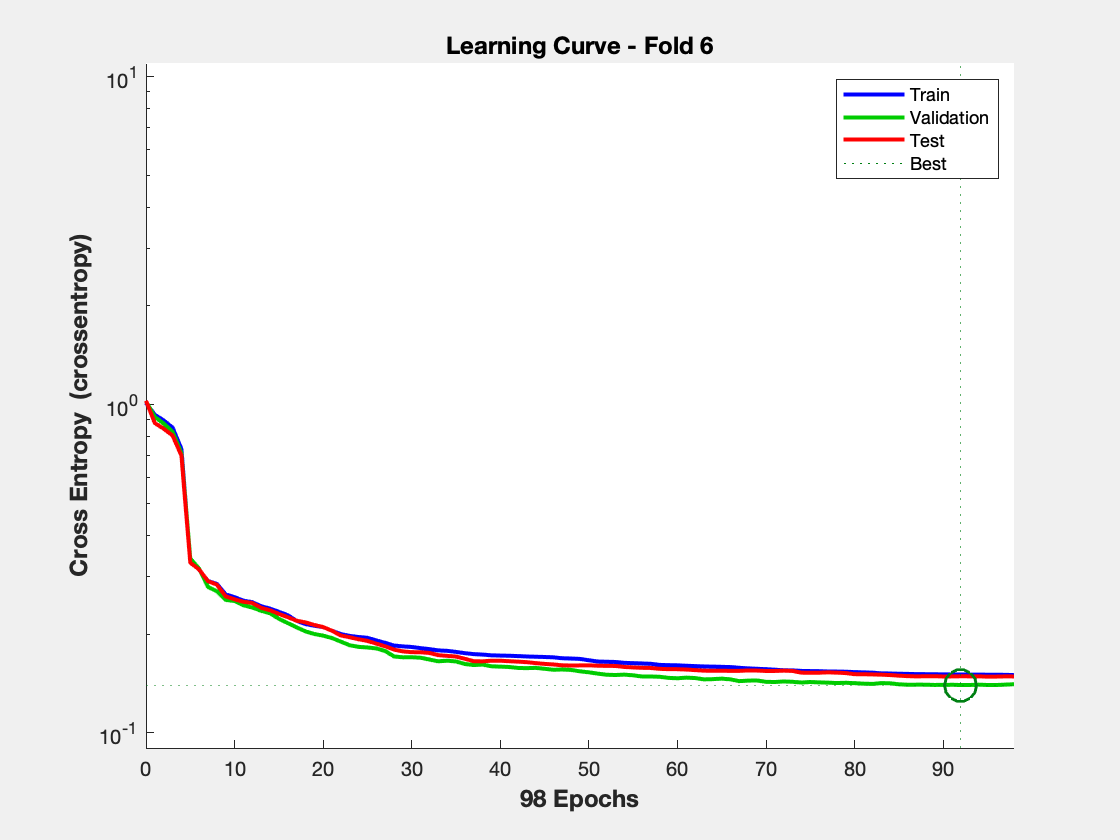

Fold 6 Accuracy: 76.20%


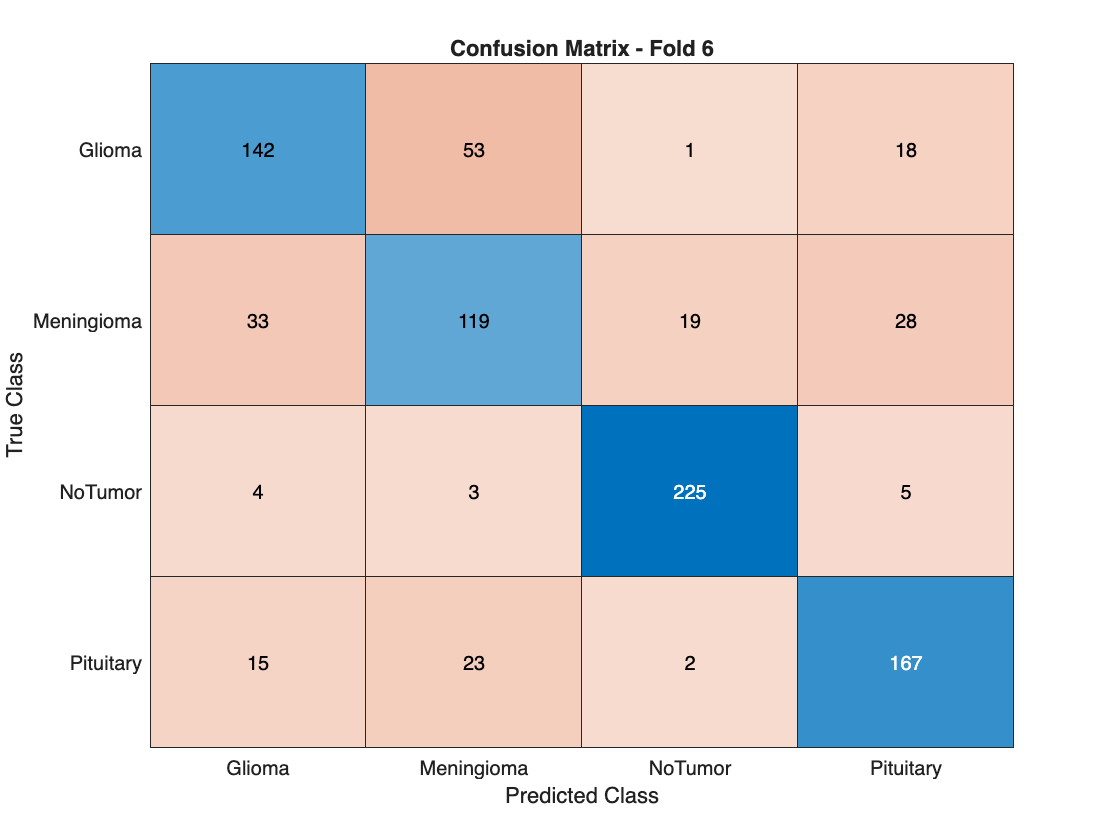


=== Fold 7 of 10 ===


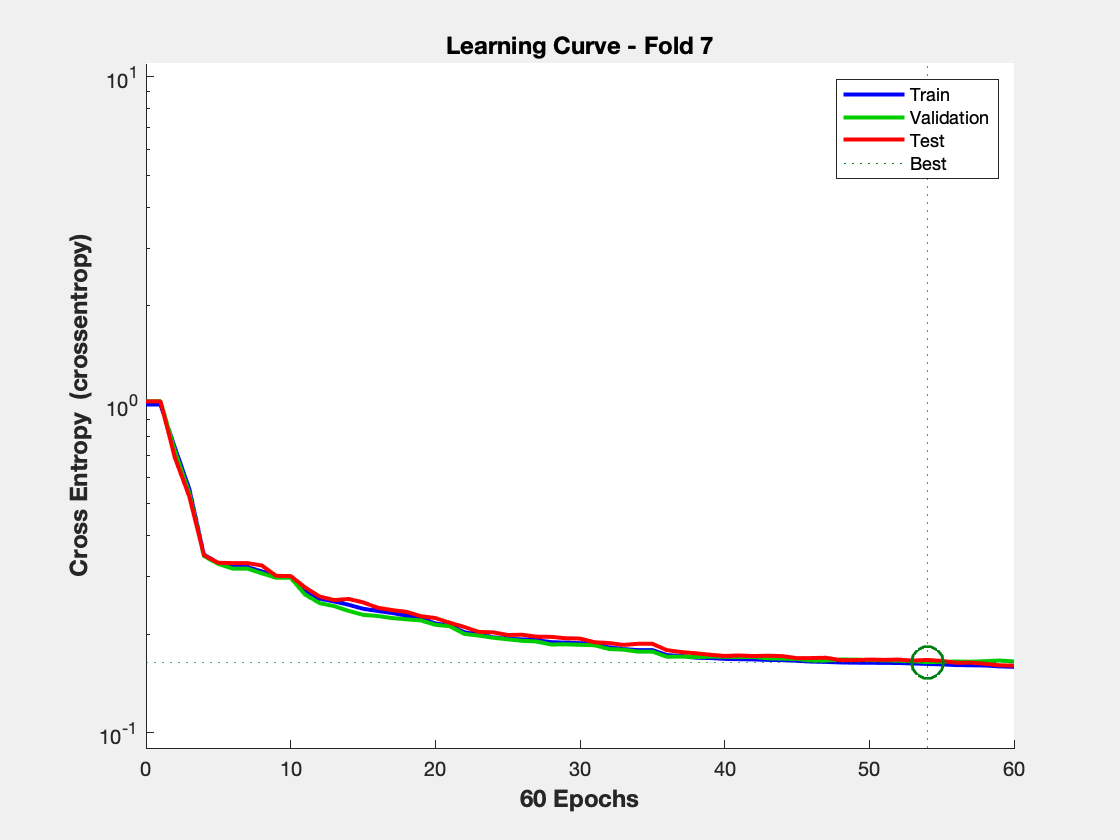

Fold 7 Accuracy: 75.03%


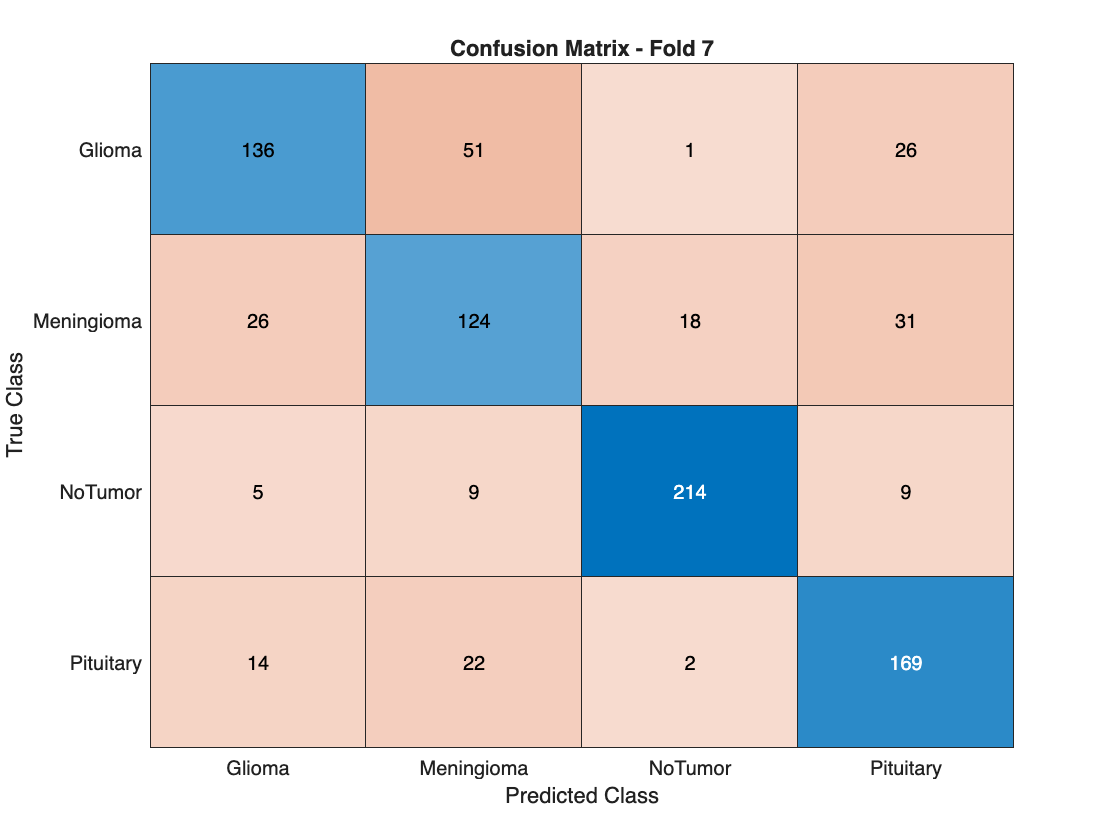


=== Fold 8 of 10 ===


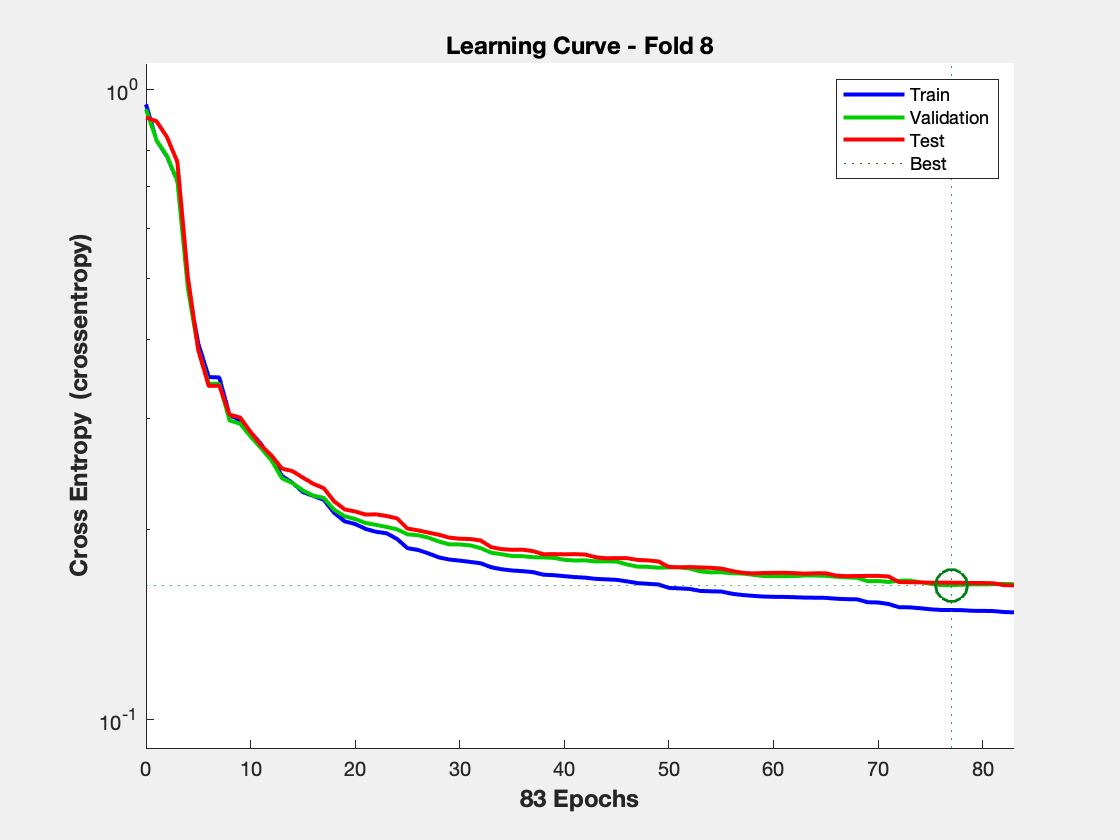

Fold 8 Accuracy: 74.80%


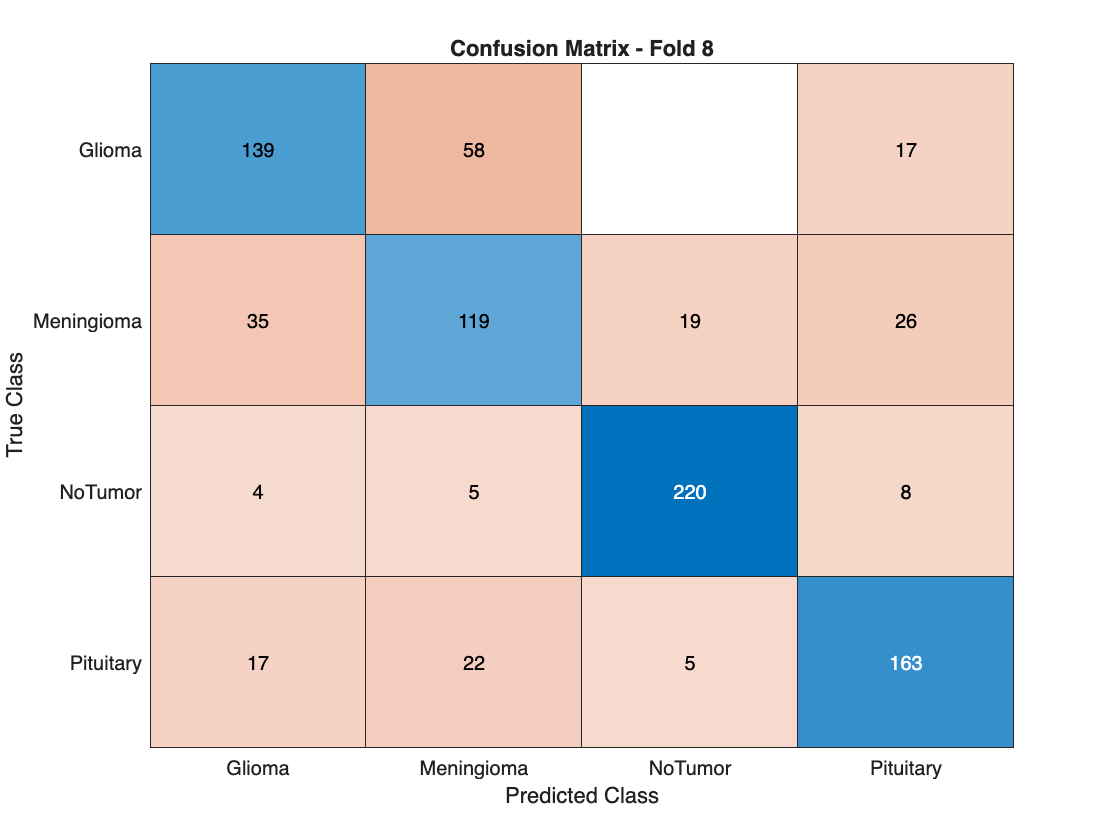


=== Fold 9 of 10 ===


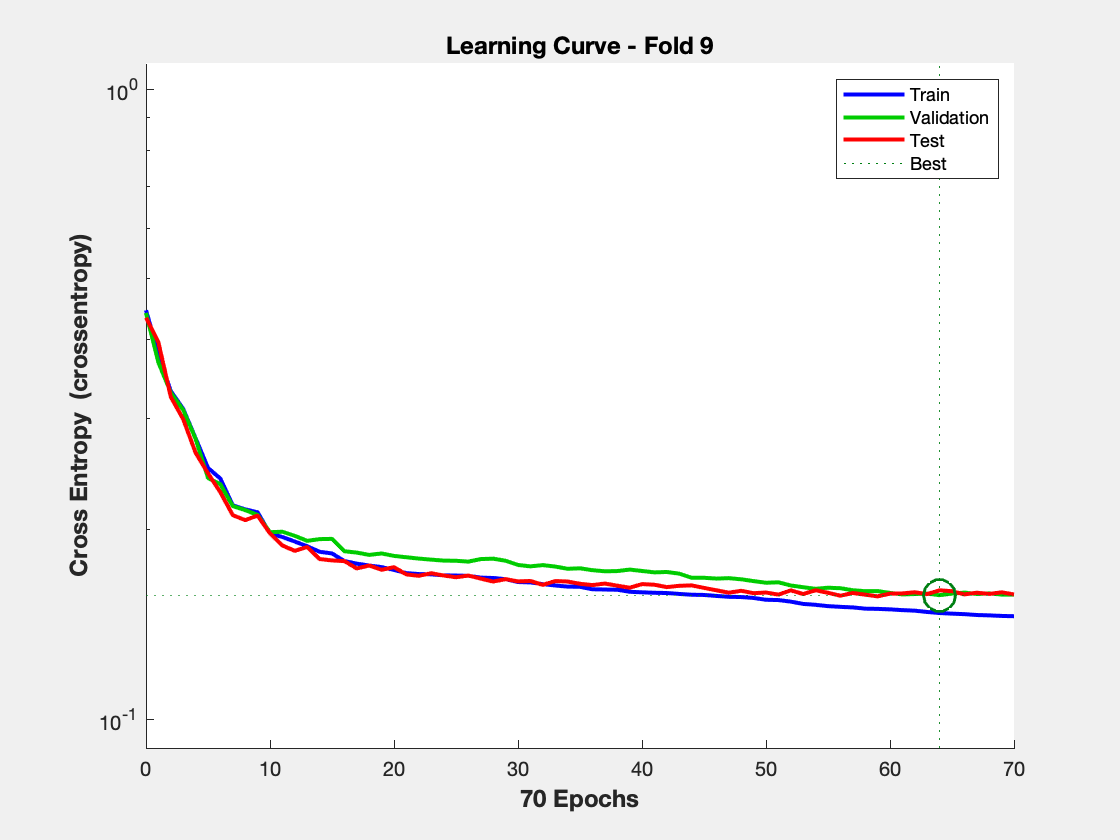

Fold 9 Accuracy: 75.26%


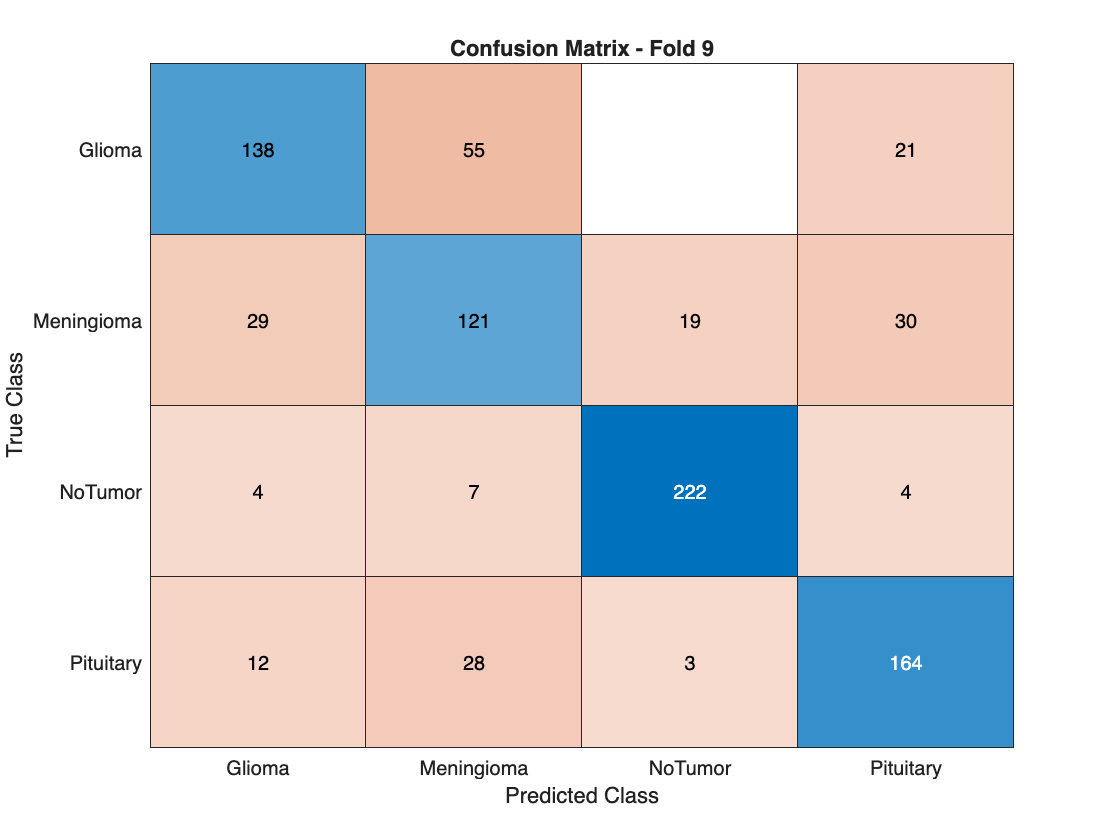


=== Fold 10 of 10 ===


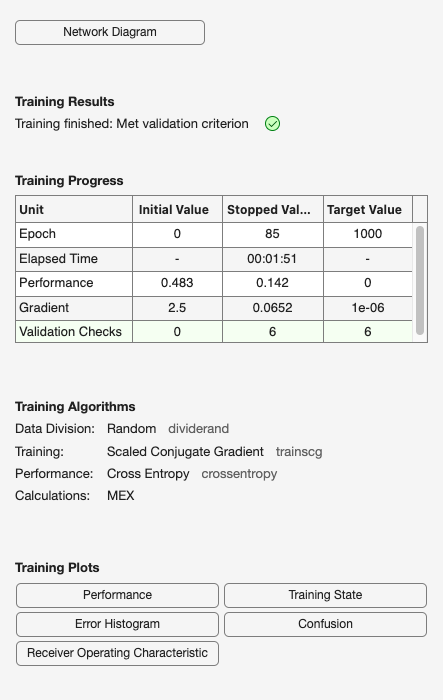

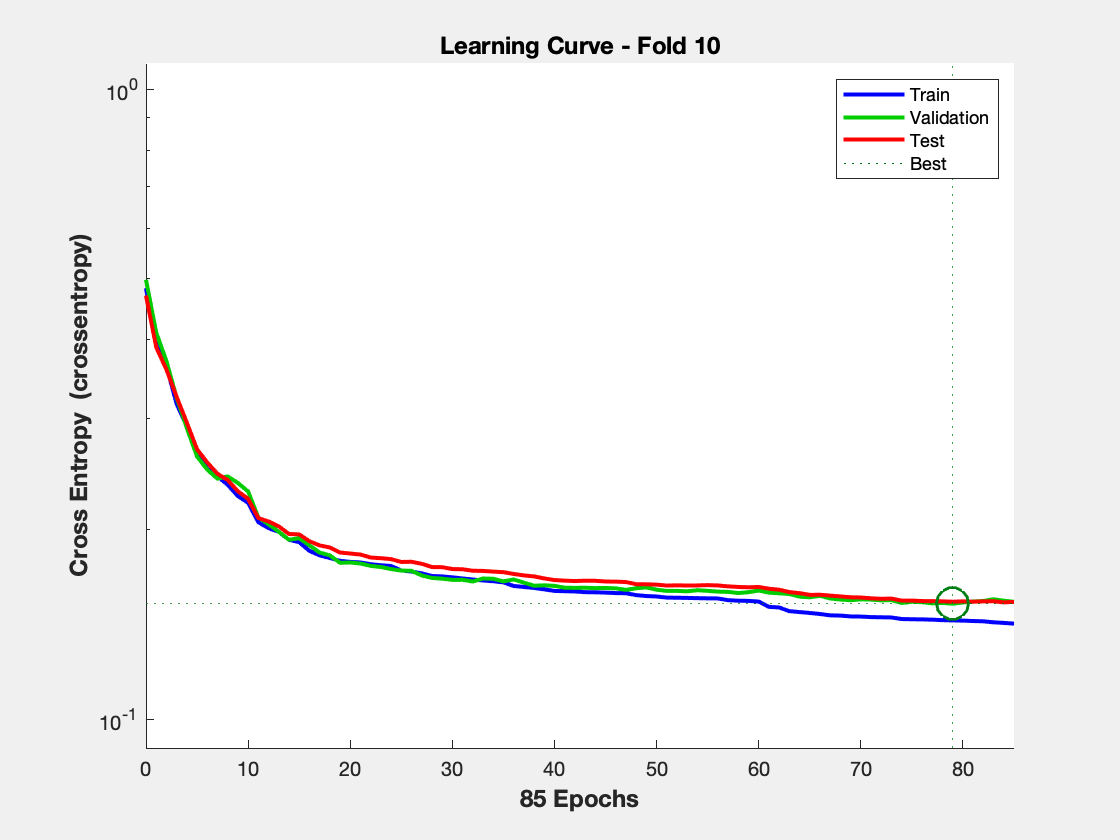

Fold 10 Accuracy: 76.66%


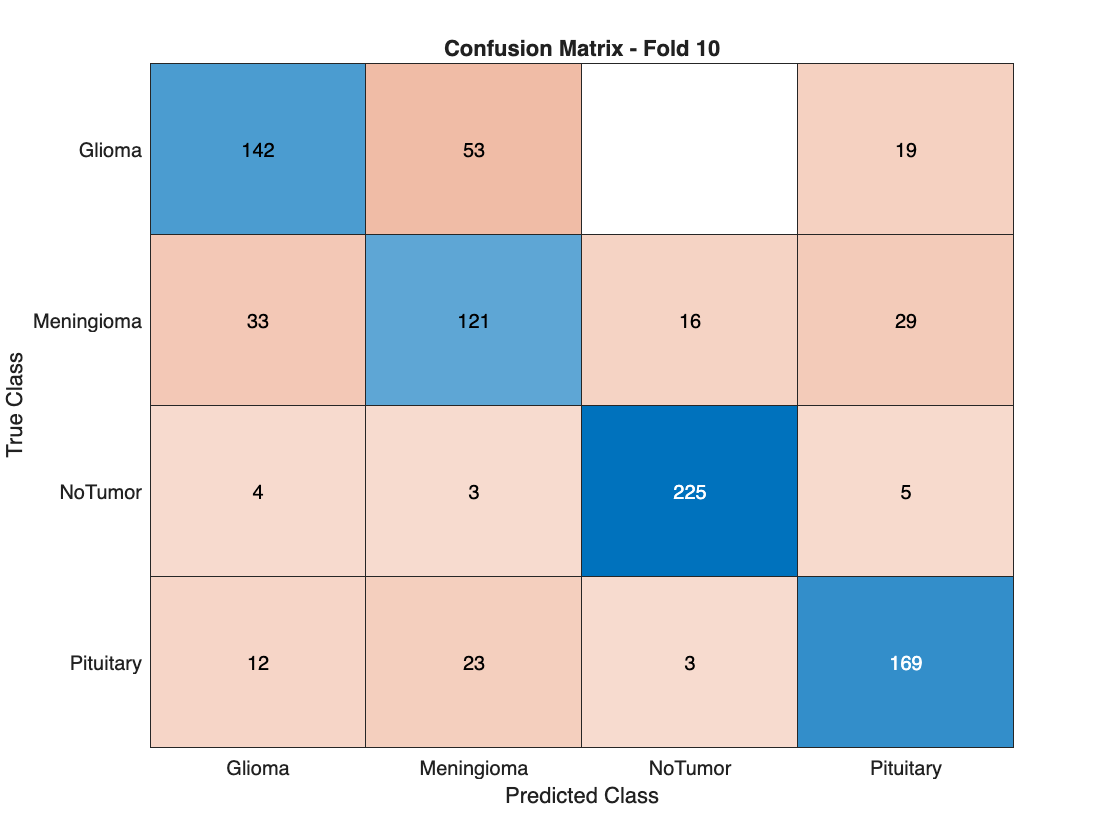

% K-FOLD CROSS VALIDATION

K = 10;
cv = cvpartition(labels, 'KFold', K);

accuracies = zeros(K, 1);
confMatrices = zeros(numClasses, numClasses, K);

for fold = 1:K
    fprintf('\n=== Fold %d of %d ===\n', fold, K);

    K_trainIdx = training(cv, fold);
    K_testIdx = test(cv, fold);

    K_XTrain = features(trainIdx, :)';
    K_YTrain = YAll(trainIdx, :)';

    K_XTest = features(testIdx, :)';
    K_YTest = YAll(testIdx, :)';

    K_net = patternnet([128, 64, 32]);
    K_net.trainFcn = 'trainscg';
    K_net.performFcn = 'crossentropy';
    K_net.trainParam.showWindow = true;

    [K_net, tr] = train(K_net, K_XTrain, K_YTrain);

    figure;
    plotperform(tr);
    title(sprintf('Learning Curve - Fold %d', fold));

    K_YPred = K_net(K_XTest);
    [~, predicted] = max(K_YPred);
    [~, actual] = max(K_YTest);

    acc = sum(predicted == actual) / numel(actual);
    accuracies(fold) = acc;
    fprintf('Fold %d Accuracy: %.2f%%\n', fold, acc * 100);

    conf = confusionmat(actual, predicted);
    confMatrices(:, :, fold) = conf;

    figure;
    confusionchart(conf, {'Glioma','Meningioma','Pituitary','NoTumor'});
    title(sprintf('Confusion Matrix - Fold %d', fold));
end

avgAcc = mean(accuracies);
fprintf('\nAverage Accuracy over %d folds: %.2f%%\n', K, avgAcc * 100);


Average Accuracy over 10 folds: 75.82%


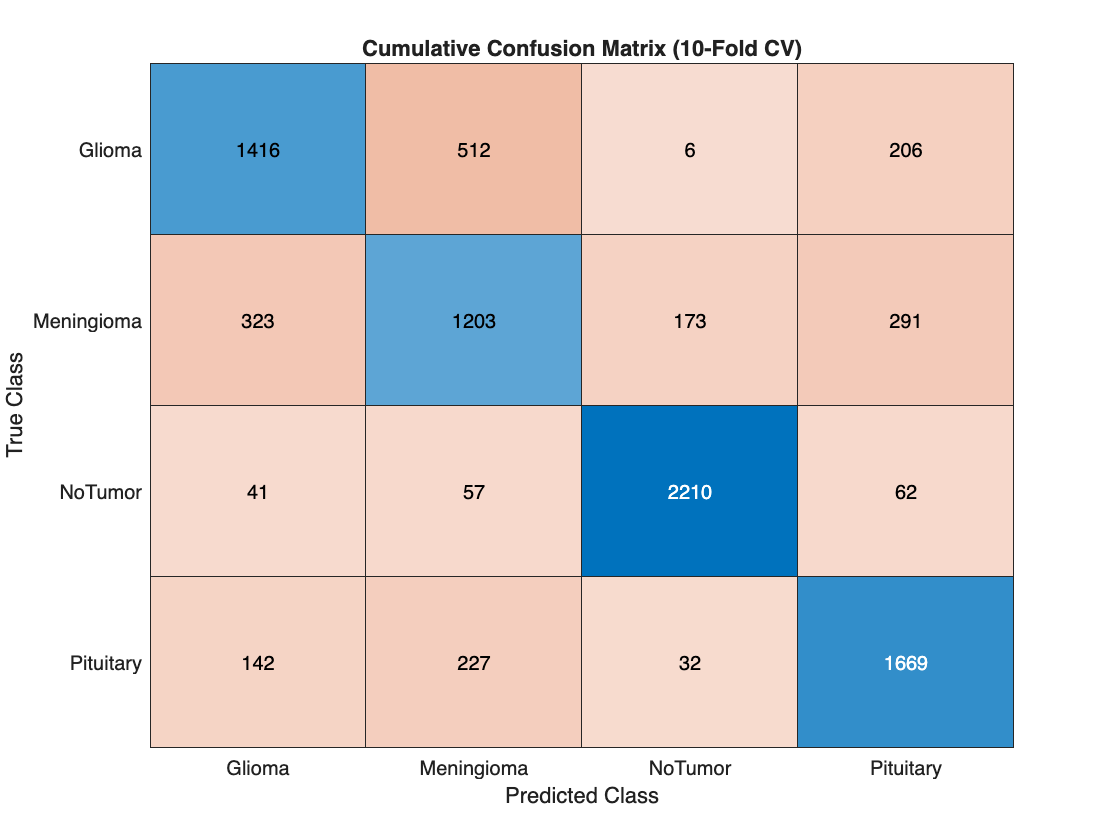


finalConf = sum(confMatrices, 3);
figure;
confusionchart(finalConf, {'Glioma','Meningioma','Pituitary','NoTumor'});
title(sprintf('Cumulative Confusion Matrix (%d-Fold CV)', K));